In this file, we use a series of use cases to test the accuracy and performance of the numerical integration method for calculating the CDF of the accumulated reward for an homogeneous Markov reward process. Two numerical integration methods were tested:

- rectangle method, as orginally presented in the paper, which is implemented in accumulated_reward_rec.m.

- trapezoid method, which is supposed to provide better accuracy, implemented in accumulated_reward_trapezoid.m.

- create_benchmark.m & create_benchmark_t.m: used to create benchmark using Monte Carlo simulation.

The first use case is from Tijms and Veldman (2000). The Q-matrix is:

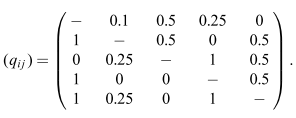

The reward vector is $\vec{r} = [5, 2, 4, 5, 4].$ 

% This is to implement the fast algorithm in Tijms and Veldman (2000)
clear; clc;
%% Parameter definition
S = 1:5; % state space
pi = [1,0,0,0,0]; % initial distribution
% Define the Q-matrix
Q = [0,.1,.5,.25,0;...
    1,0,.5,0,.5;...
    0,.25,0,1,.5;...
    1,0,0,0,.5;...
    1,.25,0,1,0];
for i = 1:5
    Q(i,i) = -1*sum(Q(i,:));
end
r = [5,2,4,5,4]; % Reward matrix
% Defining the structure para
para.S = S;
para.pi = pi;
para.Q = Q;
para.r = r;
x_max = 110; % Limit x values
T_max = 25; % Time limit

## **Rectangle integration**

To test, we calculate $P(O(t)>x_{max})
$ for $t=25$ and $x_{max} = 25.$ The theoretical value is $0.89773.$ We consider different step sizes:


$$\frac{1}{4},\frac{1}{8},\frac{1}{16},\frac{1}{32},\cdots, \frac{1}{1024}.$$


% %% Calculate P(O(t)>x) for both rectangle and trapedoid.
% % Test case 1: T_max = 25, x_max = 110. Theoretical value: 0.89773.
% % Algorithm parameters
% benchmark = .89773;
% Delta = 1/4*(1/2).^(0:10);
% result_rec = zeros(1,length(Delta));
% elasped_time_rec = zeros(1,length(Delta));
% result_trap = zeros(1,length(Delta));
% elasped_time_trap = zeros(1,length(Delta));
% for i = 1:length(Delta)
%     fprintf('%d/%d\n',i,length(Delta));
%     tic;
%     [cdf_rec, cdf_trap] = accumulated_reward_rec_trap(T_max,x_max,Delta(i),para);
%     result_rec(i) = 1 - cdf_rec;
%     elasped_time_rec(i) = toc;
%     result_trap(i) = 1 - cdf_trap;
%     elasped_time_trap(i) = elasped_time_rec(i);
% end
% save('result_use_case_1_rec_trap.mat');

We already run the simulation and saved the result so we can simply load the results.

load('result_use_case_1_rec_trap.mat');

### Accuracy and run time

We begin by visualizing the results with step sizes and run times.

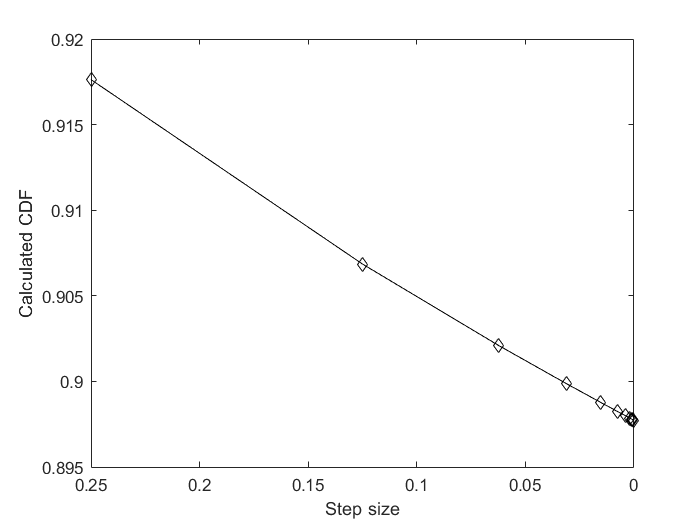

result = result_rec;
figure;
plot(Delta,result,'kd-');
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Calculated CDF');

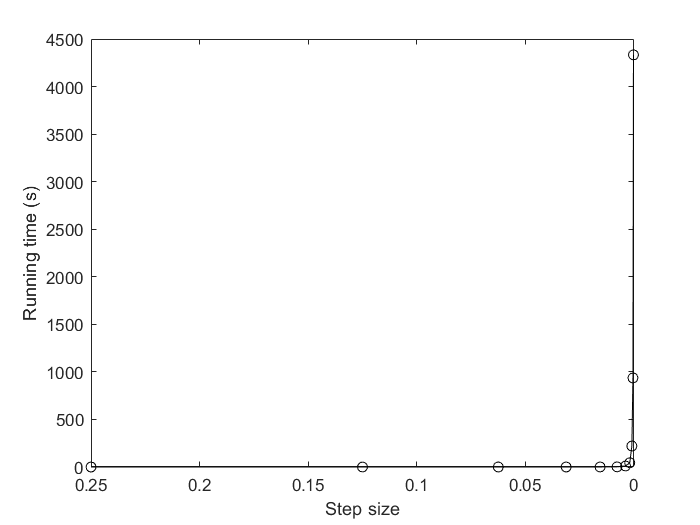

elasped_time = elasped_time_rec;
figure;
plot(Delta,elasped_time,'ok-')
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Running time (s)');

Unfortunately, the running time increases exponenetially as step sizes decrease. This is bad. How does the accuracy changes as step size changes? We plot both absolute and relative errors, as a function of step sizes. It seems that the rate of convergence is ilnear. We have a linear rate-of-convergence, but an exponential run time. So the computation is difficult.

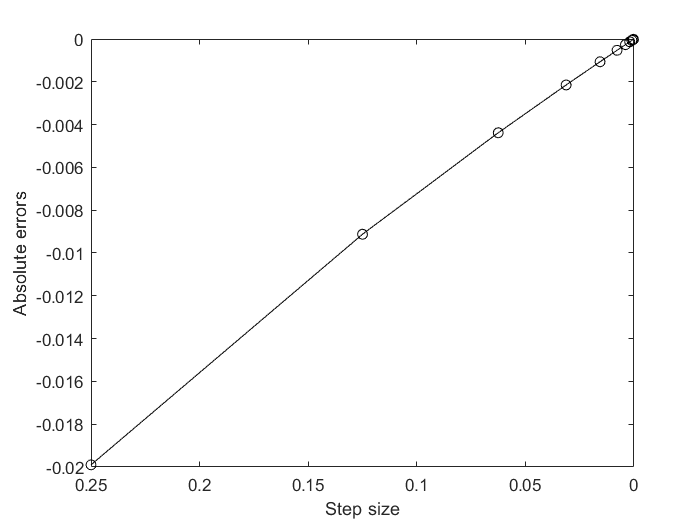

errors = benchmark - result;
relative_errors = errors./benchmark;
% Plot absolute errors.
figure;
plot(Delta,errors,'ok-')
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Absolute errors');

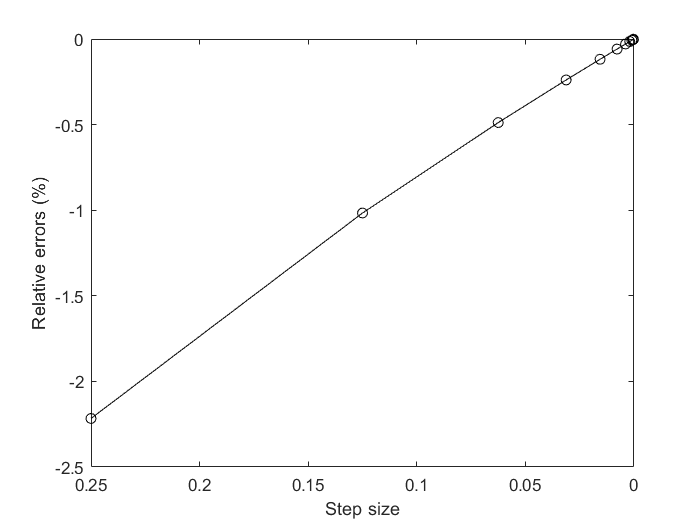

% Plot relative errors.
figure;
plot(Delta,relative_errors*100,'ok-')
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Relative errors (%)');

We might also want to investigate how absolute errors change with $h = 1/n_{points} = 1/Delta/T_{max}$

format shortE
h = Delta/T_max;
[h; errors]

ans =    1.0000e-02   5.0000e-03   2.5000e-03   1.2500e-03   6.2500e-04   3.1250e-04   1.5625e-04   7.8125e-05   3.9063e-05   1.9531e-05   9.7656e-06
  -1.9899e-02  -9.1243e-03  -4.3815e-03  -2.1477e-03  -1.0628e-03  -5.2807e-04  -2.6260e-04  -1.3034e-04  -6.4326e-05  -3.1348e-05  -1.4866e-05


The results above shows that the errors is to the order of $O(h),$ as when $h$ shrinks into half, the error also shrinks into half. This is primarily caused by the error of the numerical integration. It is known that doing numerical integration through Euler's method has an error of $O(h).$ 

In fact, this numerical integration has two sources of errors: the errors from Euler's method (physically, that means the errors arise from approximate the pdf using a recursive method), and the truncation error arising from doing a numerical integration using rectangle method.  In this particular case, as the step size is small compared to the length of $x$, the second error source does not prevail.

### Tijms' correction

In Tijms and Veldman (2000), they discovered an empirical estimation of errors:


$$\hat{error} = P(\Delta) - P(2 \Delta).$$


They used this empirical relationship to correct the estimations:


$$P_c(\Delta) = 2P(\Delta)-P(2\Delta).$$


Here we test the errors of this correction and the order of the error.

result_corrected = 2*result(2:end) - result(1:end-1);
errors_corrected = benchmark - result_corrected;
[h(2:end); errors_corrected; errors(2:end)]

ans =    5.0000e-03   2.5000e-03   1.2500e-03   6.2500e-04   3.1250e-04   1.5625e-04   7.8125e-05   3.9063e-05   1.9531e-05   9.7656e-06
   1.6501e-03   3.6140e-04   8.6084e-05   2.2098e-05   6.6567e-06   2.8627e-06   1.9223e-06   1.6882e-06   1.6299e-06   1.6153e-06
  -9.1243e-03  -4.3815e-03  -2.1477e-03  -1.0628e-03  -5.2807e-04  -2.6260e-04  -1.3034e-04  -6.4326e-05  -3.1348e-05  -1.4866e-05


From the results, it seems that this correction can "accelerate" the stablization process of the solution. Let us compare the rate of convergence of both methods.

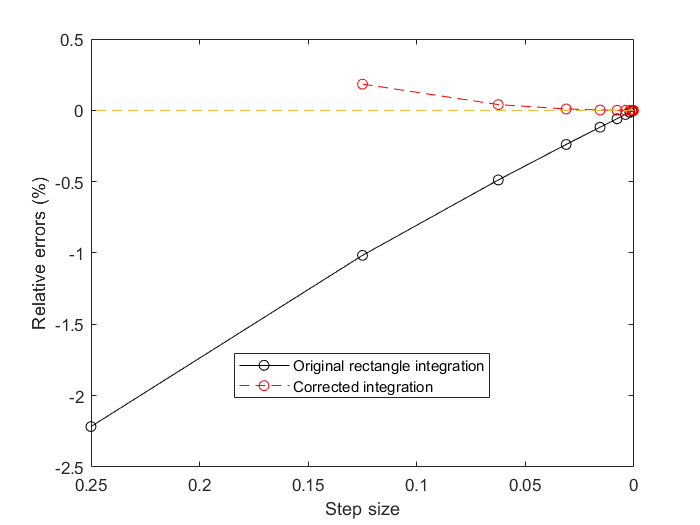

% Plot relative errors.
figure;
plot(Delta,relative_errors*100,'ok-')
xlabel('Step size');
ylabel('Relative errors (%)');
hold on;
% Calculate relative errors of the corrected method.
relative_errors_cor = errors_corrected/benchmark;
plot(Delta(2:end), relative_errors_cor*100, 'or--')
hold on
plot([0,.25],[0,0],'--')
set(gca,'Xdir','reverse');
legend('Original rectangle integration', 'Corrected integration', 'Location', "best");

### Aitken's extrapolation

Try to use series acceleration to accelerate convergence. Aitken's extrapolation is used, as it is a most useful tool for accelerating the convergence of a sequence that is converging linearly. 

Background of Aitken's extrapolation:

Given a sequence $X = (x_n)_{n\in N}$, one associates with this sequence the new sequence 


$$AX = \left(\frac{x_n x_{n+2} - x_{n+1}^2}{x_n + x_{n+2} - 2x_{n+1}}\right)_{n\in Z^*},$$


which can, with improved [numerical stability](https://en.wikipedia.org/wiki/Numerical_stability), also be written as 


$$(AX)_n = x_n - \frac{(\Delta x_n)^2}{\Delta^2 x_n},$$


or equivalently as 


$$(AX)_n = x_{n+2} - \frac{(\Delta x_{n+1})^2}{\Delta^2 x_n} = x_{n+2} - \frac{(x_{n+2} - x_{n+1})^2}{(x_{n+2} - x_{n+1}) - (x_{n+1} - x_{n})}$$


where 


$$\Delta x_n = (x_{n+1} - x_n), \Delta x_{n+1} = (x_{n+2} - x_{n+1}),$$


and 


$$\Delta^2 x_n = x_n - 2 x_{n+1} + x_{n+2} = \Delta x_{n+1} - \Delta x_n, n =0,1,2,\ldots$$


The idea is that the new series $AX$ converges to the same value of $X,
$ but with a faster speed. 

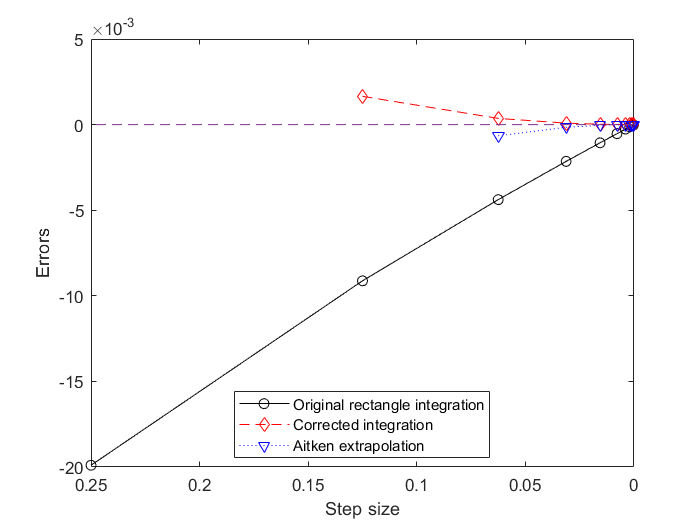

%% Try to accelerate convergence using Aitken's extrapolation method.
% Calculate the accelerated series AX.
difference = result(2:end) - result(1:end-1);
Delta_x_n = difference(1:end-1);
Delta_x_np1 = difference(2:end);
Delta_square_x_n = Delta_x_np1 - Delta_x_n;
AX = result(1:end-2) - Delta_x_n.^2./Delta_square_x_n;
% Evaluate the errors and convergence rate.
errors_AX = benchmark - AX;
% Plot errors.
figure;
% Original
plot(Delta,errors,'ok-')
xlabel('Step size');
ylabel('Errors');
hold on;
% Correction based on the paper
plot(Delta(2:end), errors_corrected, 'dr--')
hold on;
% Aitken's extrapolation
plot(Delta(3:end),errors_AX,'vb:');
hold on;
plot([0,.25],[0,0],'--')
set(gca,'Xdir','reverse');
legend('Original rectangle integration', 'Corrected integration', 'Aitken extrapolation', 'Location', "best");

[h(1:end-2); errors_AX]

ans =    1.0000e-02   5.0000e-03   2.5000e-03   1.2500e-03   6.2500e-04   3.1250e-04   1.5625e-04   7.8125e-05   3.9063e-05
  -6.5198e-04  -1.5902e-04  -3.8323e-05  -8.3516e-06  -8.7782e-07   9.8861e-07   1.4550e-06   1.5716e-06   1.6007e-06


## Trapedoid integration

It is known that if we move from rectangle integration (or Rieman sum, in this case, the right Riemann sum) to trapedoid integration, the error decreases from $O(h)$ to $O(h^2)$. Let's test if it is true in this case. The function for trapedoid integration is accumulated_reward_trapezoid.m. The test setting is the same as the rectangle method. 

### Comparison to rectangle integration

We already did the simulation so just need to load the results. In the following, we compare with the rectangle method:

- Accuracy.

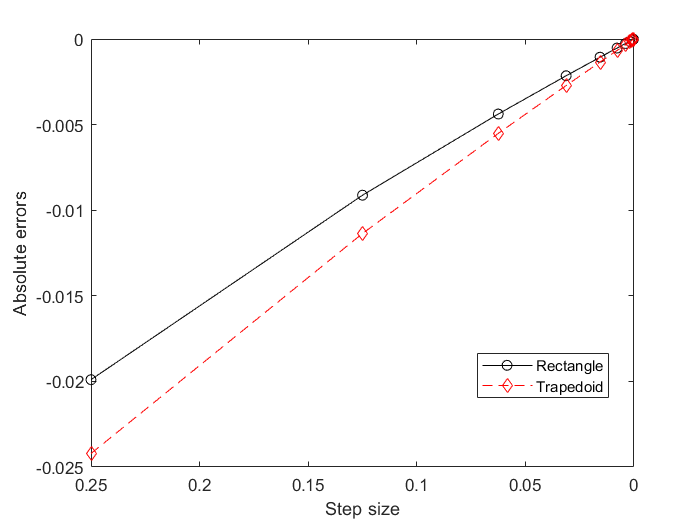

% Errors of the trapedoid integration.
errors_trap = benchmark - result_trap;
% Compare the errors.
figure;
plot(Delta,errors,'ok-')
set(gca,'Xdir','reverse');
xlabel('Step size');
ylabel('Absolute errors');
hold on;
plot(Delta,errors_trap,'dr--');
legend('Rectangle','Trapedoid','Location','best');

% Show the error V.S. h for both method.
[h; errors; errors_trap]

ans =    1.0000e-02   5.0000e-03   2.5000e-03   1.2500e-03   6.2500e-04   3.1250e-04   1.5625e-04   7.8125e-05   3.9063e-05   1.9531e-05   9.7656e-06
  -1.9899e-02  -9.1243e-03  -4.3815e-03  -2.1477e-03  -1.0628e-03  -5.2807e-04  -2.6260e-04  -1.3034e-04  -6.4326e-05  -3.1348e-05  -1.4866e-05
  -2.4213e-02  -1.1361e-02  -5.5139e-03  -2.7168e-03  -1.3480e-03  -6.7082e-04  -3.3402e-04  -1.6606e-04  -8.2186e-05  -4.0279e-05  -1.9332e-05


From the comparison above, the conclusion is that in this particular case, trapedoid integration does not improve the accuracy compared to rectangle integration.

## Compare to Monte Carlo simulation.

We use a Monte Carlo simulation to compare the computational efficiencies and simulation accuracy. A sample size of $10^7

$ is used for Monte Carlo simulation. The errors of the Monte Carlo simulation is estimated by its $95\%$ confidence bound and the sample standard deviation. We have run the simulation and store the result in "result_benchmark.mat".

% Load the MC result.
load('result_benchmark.mat');
NS = 1e7;
% Calculate the cdf
result_MC = sum(P_O_time>x_max)/NS

result_MC =    8.9770e-01


% Confidence interval
alpha = .05;
cal_sigma_hat = @(N,p) sqrt(1/(N-1).*(p.*(1-p)));
cal_ci = @(N,p,alpha) [p-norminv(1-alpha/2)*cal_sigma_hat(N,p),...
    p+norminv(1-alpha/2)*cal_sigma_hat(N,p)];
result_MC_CI = cal_ci(NS,result_MC,alpha)

result_MC_CI =    8.9751e-01   8.9788e-01


error_MC = benchmark - result_MC

error_MC =    3.3100e-05


sample_std = cal_sigma_hat(NS,result_MC)

sample_std =    9.5832e-05


It can be seen that the error of MC is an order of $10^{-5}
$ and the computation time is $1.6475\times10^3 $ (s). If we use rectangle integration plus Aitken's extrapolation, achieving the same degree of error would require only $0.4821
$ (s). 

From the experiment so far, we can conclude that the most efficient method is to use trapedoid integration plus Aitken's extrapolation.

## Maximal step size considering the transition rates

For a Markov chain with transition rate matrix $Q$, the maximal step size $\Delta
$ should satify:

$\max_i P(n_{i,j}(\Delta)\ge 2) \le $A given threshold.

$\max_i \sum_{j=0}^1 e^{-\lambda_i \Delta} \frac{(\lambda_i \Delta)^j}{j!}$.

$\max_i \left(1-poisscdf(1,\lambda_i\Delta)\right) = \left(1-poisscdf(1,\min(\lambda_i)\Delta)\right) \le
$Threshold.

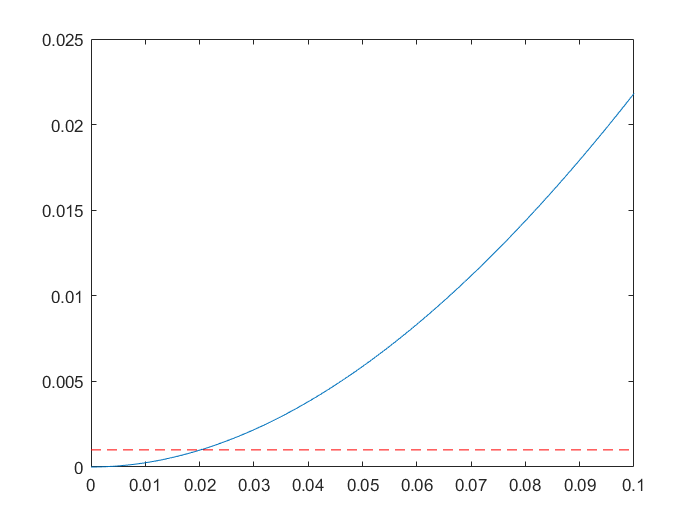

p_th = 1e-3; % Threshold probability.
% Take the exit rates.
exit_rate = zeros(1,size(Q,1));
for i = 1:size(Q,1)
    exit_rate(i) = -Q(i,i);
end
q_max = max(exit_rate); % Minimal exit rate.
% Define a handle to calculate the icdf of Poisson.
cal_exceed_prob = @(x) 1 - poisscdf(1, q_max*x);
x_trial = linspace(0,.1,1e3);
figure
plot(x_trial, cal_exceed_prob(x_trial),'-');
line([0,.1],[1e-3,1e-3],'Color','red','LineStyle','--');

When $\Delta
$ is larger than roughly $0.02,$ there will be very large approximation error due to using a stepwise approximation to the Markov system.

## Test iteration until error tolerance

We designed a new function accumulated_reward_numit.m, which runs an iterative numerical integration with decreased sample size, until the difference between two adjacent simulations is below tol. We test its performance here.

% This is to test accumulated_reward_numit.m
clear; clc;
%% Parameter definition
S = 1:5; % state space
pi = [1,0,0,0,0]; % initial distribution
% Define the Q-matrix
Q = [0,.1,.5,.25,0;...
    1,0,.5,0,.5;...
    0,.25,0,1,.5;...
    1,0,0,0,.5;...
    1,.25,0,1,0];
for i = 1:5
    Q(i,i) = -1*sum(Q(i,:));
end
r = [5,2,4,5,4]; % Reward matrix
% Defining the structure para
para.S = S;
para.pi = pi;
para.Q = Q;
para.r = r;
x_max = 110; % Limit x values
T_max = 25; % Time limit

%% Run the test.
benchmark = .89773;
Delta = 1/4*(1/2).^(0:10); % Search space.
tol = 1e-5;
format longE;
tic;
[cdf, epsilon] = accumulated_reward_numit(T_max,x_max,Delta,para,tol)

cdf =      1.022692645781715e-01


epsilon =      7.066069218769622e-06


result_numit = 1-cdf

result_numit =      8.977307354218285e-01


elasped_time_numit = toc

elasped_time_numit =      1.307390420000000e+01


We also test the algorithm to simultaneously calculate the cdf at a vector of t. Test vector: $t=[0,5,10,15,20,25].$

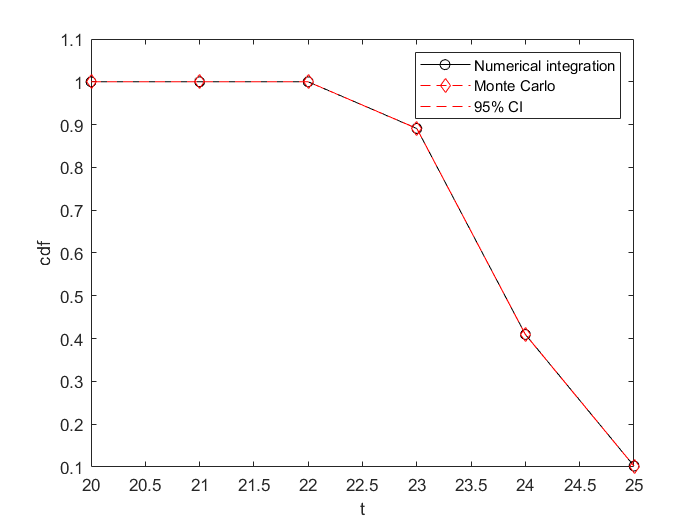

t = 20:25;
% % Create benchmark
% n_s = 1e7;
% [cdf_t_MC, ci_t_MC, elasped_time_cdf_t_MC] = create_benchmark_t(t,n_s);
% save('result_benchmark_cdf_t','cdf_t_MC', "elasped_time_cdf_t_MC", "ci_t_MC");
load('result_benchmark_cdf_t.mat');
% Test the numerical integration.
tic;
[result_numit_t, epsilon_t] = accumulated_reward_numit(t,x_max,Delta,para,tol);
elasped_time_numit_t = toc;
% Visualize the results
figure
plot(t,result_numit_t,'-ko');
hold on;
plot(t,cdf_t_MC,'r--d',t,ci_t_MC,'--r');
xlabel('t');
ylabel('cdf');
legend('Numerical integration','Monte Carlo','95% CI');